%% Force of GRACE PAM

% INPUTTING PARAMETERS
%Current values show dimensions of final PAM design

%Set L_1, the length of deflated PAM (m)
L_1=0.04;
%L_1 = input("Enter the length of deflated PAM (metres)");
%Set D_1, the diameter of end of PAM (m) 
D_E=0.016;
%D_E = input("Enter the diameter of end of deflated PAM (metres)");
%Set D_1, the diameter of centre of deflated PAM (m) 
D_1=0.045;
%D_1 = input("Enter the maximum diameter of uninflated PAM (metres)");


%CALCULATING FORCE

%Set up range of lengths of contracting PAM 
%(factor=0.9 means PAM is 90% of original length, contraction is 10% of original length)
factor=0.5:0.01:0.99;
%factor=0.9

factor = 0.9900

L_2=L_1*factor;
%For plot later
factorpercent=(factor.*100);

%Set up the equations needed to find PAM's Force
%Calculate half length of  PAM
l_1=L_1./2;
l_2=L_2./2;
%Calculate volume of deflated PAM (truncated cones)
V_1=2*((1/3).*pi.*l_2.*((D_E/2).*(D_1/2) +(D_E/2).^2 +(D_1/2).^2));
%Calculate diameter of inflated PAM at widest point
D_2=D_E+ (    2*sqrt  (  ((D_1-D_E)/2)^2+l_1.^2-l_2.^2  )      );
%Calculate volume of inflated PAM (truncated cones)
V_2=2*((1/3).*pi.*l_2.*((D_E/2).*(D_2/2) +(D_E/2).^2 +(D_2/2).^2));
%Calculate difference between deflated and inflated volume
dV=V_2-V_1;
%Calculate difference between deflated and inflated length
dL=L_1-L_2;

p = 5000

F = 5.0061

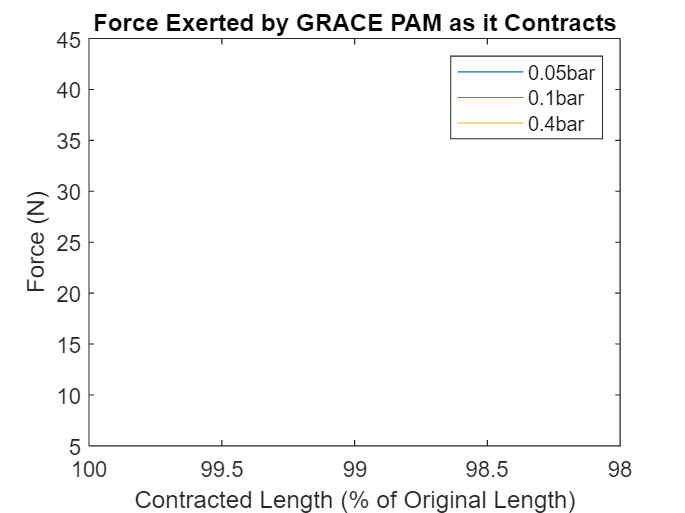

%PLOTTING GRAPH

%Calculate force PAM generates
for p=[5000,10000,40000]
%for p=[10000,50000,100000]
%for p = 10000:10000:100000
F=2/3*p.*dV./dL;
%Plot force against contraction
plot(factorpercent, F)
hold on
end

xlabel('Contracted Length (% of Original Length)')
ylabel('Force (N)')
title('Force Exerted by GRACE PAM as it Contracts')
set(gca, 'XDir','reverse')
legend('0.05bar','0.1bar','0.4bar')

%legend('10kPa','50kPA','100kPA')
%legend ('1 bar','2 bar','3 bar')
